# Tutorial on color matching (Psych 221)

This tutorial  introduces several computational methods in color.  These calculations show how to:

- Compute the XYZ values of a light source, in this case a display monitor

- Set the monitor output to achieve these XYZ levels and match a target

- Manage the nonlinear relationship between frame buffer and emitted light output

- Compute and plot the xy chromaticity values

**Author**: Wandell, January 1996

**Duration:**  90 minutes

% Initialize ISETCam
ieInit

## Measuring the display primary SPDs

To match the color of a light in the world with the light from a display, we must calibrate the display.  The key color properties of any display are the spectral power distributions (SPDs) of the primary lights in the display.   

We measure these functions using a spectral radiometer, a device that measures the average power per nanometer emitted from a small spatial area on the display. I measured the spectral power distributions of the primaries from a monitor in my lab (circa 1995). These were measured when the primaries were set to maximum value (1).  The SPDs of the three primaries are stored in three columns of the matrix called "phosphors" in this tutorial.  (Back in the day, the primary SPDs were determined by phosphors painted onto the front of the display). 

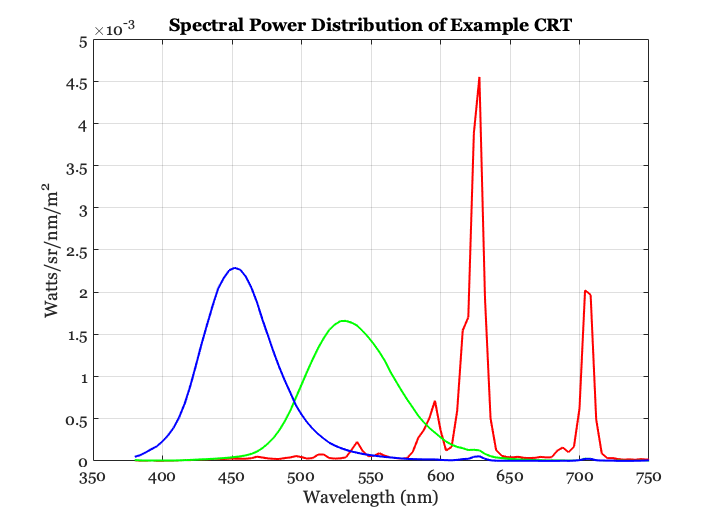

% Read in a display
thisDisplay = 'CRT-Dell';
% thisDisplay = 'LCD-Apple';
d = displayCreate(thisDisplay);

phosphors  = displayGet(d,'spd');
wavelength = displayGet(d,'wave');

% Plot the display phosphors
ieNewGraphWin;
plot(wavelength,phosphors(:,1),'r-', ...
    wavelength,phosphors(:,2), 'g-',...
    wavelength,phosphors(:,3),'b-', ...
    'LineWidth',2);
xlabel('Wavelength (nm)'), ylabel('Watts/sr/nm/m^2')
title('Spectral Power Distribution of Example CRT');
set(gca,'xlim',[350 750]), grid on

## Calculating the XYZ values of the primaries

To measure the XYZ values of these display primaries, we load in the  $\bar{x}$ , $\bar{y}$ $\bar{z}$  functions defined by the CIE.  These are also stored in the columns of a matrix, called XYZ.  Because these functions are so widely used, they are stored in the data directory of ISETCam.  

**N.B.** It is important to remember that the data from the spectroradiometer are in energy units. For this reason, the XYZ functions we read in are designed to work with data measured in units of energy.  If the measurements you make are in units of photons (quanta), then you should load the file 'XYZQuanta'.

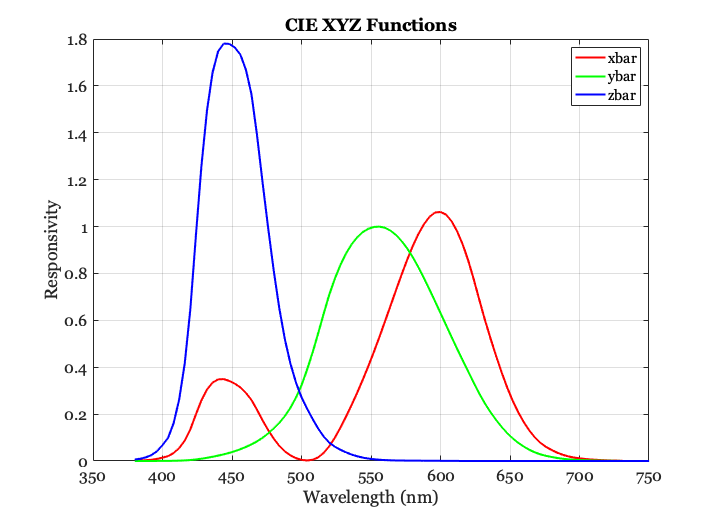

ieNewGraphWin;
XYZ = ieReadSpectra('XYZEnergy',wavelength);
plot(wavelength, XYZ(:,1:3),'LineWidth',2);
xlabel('Wavelength (nm)'), ylabel('Responsivity')
legend('xbar','ybar','zbar');
title('CIE XYZ Functions');
set(gca,'xlim',[350 750]), grid on

The principle of calculating (X,Y, Z) values for each of the display primaries is simply to multiply the phosphor matrix times the XYZ matrix. The phosphors are in the columns of the matrix, and the $\bar{x}$ , $\bar{y}$ $\bar{z}$  functions are in the rows of the matrix on the left.

maxXYZ = XYZ'*phosphors;
disp(maxXYZ);

    0.0144    0.0117    0.0086
    0.0079    0.0246    0.0044
    0.0008    0.0040    0.0450



The problem, however, is that this matrix calculation doesn't account for some details necessary to account for the measurement units.  Most important, we need to account for the sample spacing of the wavelengths.  There are also physical constants that were agreed upon by standards committees.  Rather than trying to remember this, there is a routine that manages these factors.

% The function that calculates the CIE XYZ from Energy measurements
maxXYZ = ieXYZFromEnergy(phosphors',wavelength(:));

Remember that the luminance is the Y-values.  The luminance at the maximum value is the Y-value (2nd row) the maxXYZ matrix.  The units of display luminance are $cd/m^2$ also sometimes called *nits *(an older notation, not ISO standard notation).

maxXYZ(2,:)

ans =    31.9501   67.1483   11.0284


The total luminance the display can reach, with all three primaries are set to maximum, is given by the sum of the three Y-values.  Modern displays usually have a maximum luminance  above 100 $cd/m^2$ .

sum(maxXYZ(2,:))

ans = 110.1268

## Using the CMFs to match a target (linear display, gamma = 1)

Imagine this problem - which is a true engineering challenge from the 1980s.  Suppose you send a space ship to the surface of mars.  The ship sends back a measurement of the spectral power distribution from the Martian scene.  Let's load it.  In this case, suppose that the data are spaced in 5 nm steps.

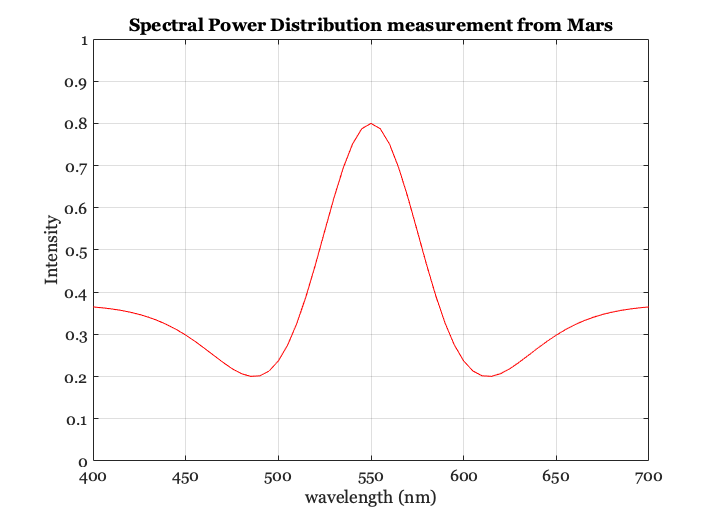

% Reload the XYZ Energy data, but sampled in 5 nm steps 
wavelength = 400:5:700;
d = displayCreate(thisDisplay,wavelength);
phosphors  = displayGet(d,'spd');
XYZ = ieReadSpectra('XYZ',wavelength);

% The data from mars
marsSPD = ieReadSpectra('mars.mat',wavelength);
clf,plot(wavelength,marsSPD,'r-')
set(gca,'ylim',[0 1])
grid on, xlabel('wavelength (nm)'); ylabel('Intensity')
title('Spectral Power Distribution measurement from Mars');

### Calculating the XYZ values of the data from Mars

Now, how do we set the monitor intensities so that what we see on a display is a visual match to the spectrum measured on Mars?  We use the XYZ color-matching functions.  First, measure the values for the Martian spectrum

marsXYZ = ieXYZFromEnergy(marsSPD',wavelength(:));

Recall that the monitor color properties are determined by the relative intensity of the outputs of the monitor phosphor SPDs.  Suppose these intensities are [r,g,b]'.  Then the monitor output is  phosphors*[r,g,b]'.  For example, when the red phosphor only is on the spectrum is

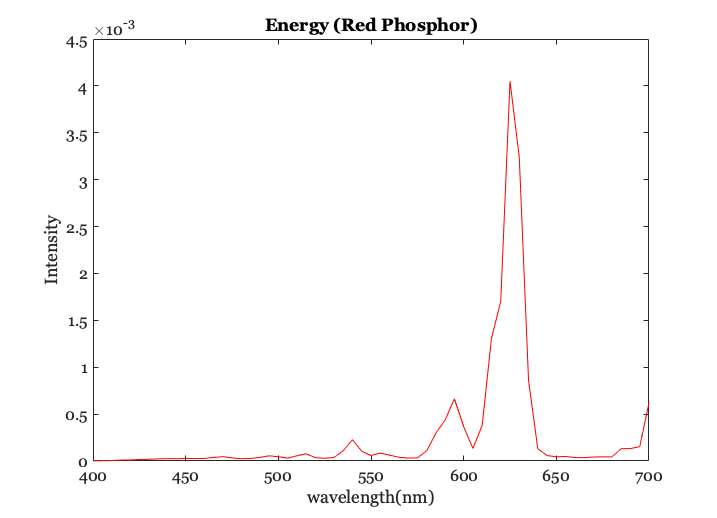

plot(wavelength, phosphors*[1 0 0]', 'r-');
xlabel('wavelength(nm)'); ylabel('Intensity')
title('Energy (Red Phosphor)');

When the red and blue are on, the output is

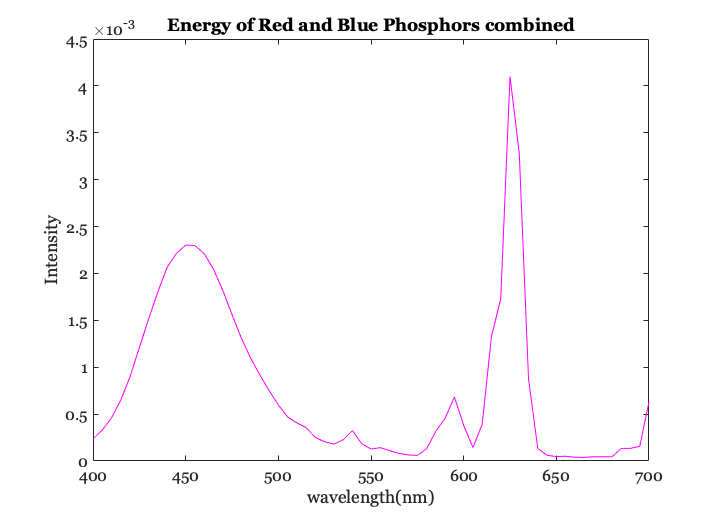

plot(wavelength, phosphors*[1 0 1]','m-');
xlabel('wavelength(nm)'); ylabel('Intensity')
title('Energy of Red and Blue Phosphors combined');

### Converting primary RGB values to XYZ values

To find the relationship between the [r,g,b] values and the monitor XYZ outputs, we only need to multiply the output times the XYZ functions. Hence, there is a matrix that maps the linear monitor intensities into the XYZ values.  This 3x3 matrix is

RGB2XYZ = ieXYZFromEnergy(phosphors',wavelength)'

RGB2XYZ =    38.5358   31.9654   23.5896
   21.1900   67.1357   11.9903
    2.0578   11.0552  122.7629


Take a look at this matrix and think about its entries.  Notice that the first column contains the XYZ values associated with the red phosphor, the middle with the green, and the third column is associated with the blue.  These values should make sense to you given the shapes of the XYZ functions we have already plotted.

### Converting primary Martian  XYZ values to monitor RGB values

Now, to represent the Martian spectrum on our display, we need to compute only one more thing.  How do we set the [r,g,b] values when we know the XYZ values of the spectrum?  For this, we need a matrix that converts XYZ to monitor linear gun intensities, the inverse of the matrix that we have.  So, we calculate this new matrix as

XYZ2RGB = inv(RGB2XYZ)

XYZ2RGB =     0.0349   -0.0158   -0.0052
   -0.0111    0.0201    0.0002
    0.0004   -0.0016    0.0082



% These are the RGB values we use to display the Martian spectrum
marsRGB = XYZ2RGB*marsXYZ' %#ok<MINV> 

marsRGB =   279.6730
  423.2905
  130.1053



% Let's make sure the XYZ from the Martian spectrum  
ieXYZFromEnergy(marsSPD',wavelength)

ans = 	1.0e+04 *

    2.7377    3.5904    2.1227



% match the XYZ from the display RGB 
ieXYZFromEnergy((phosphors*marsRGB)',wavelength)

ans = 	1.0e+04 *

    2.7377    3.5904    2.1227


### Metamers, not Isomers

The spectrum we  display is NOT equal to the spectrum we measured on Mars.  But to our eyes, the display spectrum and Martian spectrum should match.  Here is a comparison of the two different SPDs.

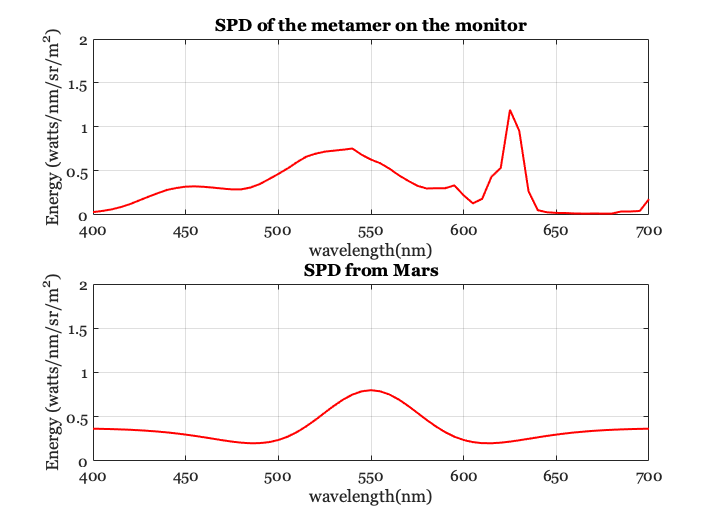

ieNewGraphWin;
subplot(2,1,1)
plot(wavelength,phosphors*marsRGB,'LineWidth',2);
title('SPD of the metamer on the monitor');
set(gca,'ylim',[0 2]); grid on
xlabel('wavelength(nm)');ylabel('Energy (watts/nm/sr/m^2)')

% This will be a perceptual (XYZ) match to the Martian spectrum
subplot(2,1,2) 
plot(wavelength,marsSPD,'LineWidth',2);
set(gca,'ylim',[0 2]); grid on
title('SPD from Mars');
xlabel('wavelength(nm)');ylabel('Energy (watts/nm/sr/m^2)')

## Nonlinear displays - Gamma tables and inverse gamma tables

The calculations up to this point assumed we had a linear display:  the RGB value is proportional to the display primary intensity. This linearity is almost never true of real displays; there is a nonlinear relationship between the value we set in the frame-buffer and the intensity of the display primary. 

Hence, to implement these calculations in a a real display we must choose a frame-buffer entries so that we obtain the linear intensity outputs we have just calculated.  Adjusting for the nonlinear relation is called gamma correction.

An example of a "Gamma" function relating frame-buffer value to emitted light intensity is shown here:

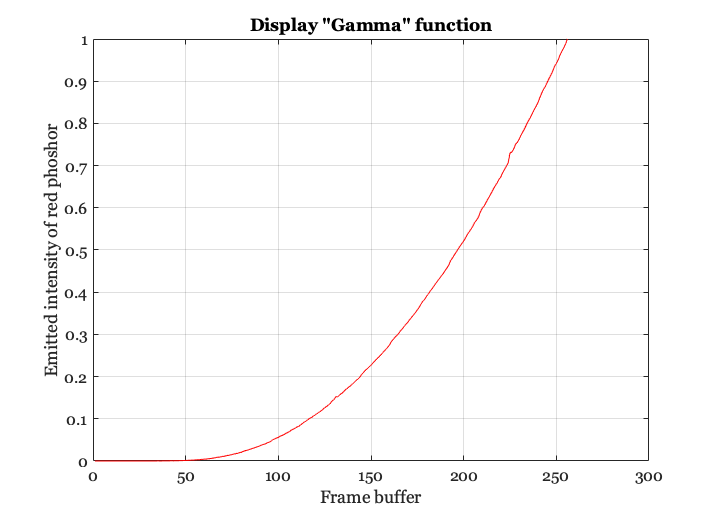

load cMatch/monitorGam
ieNewGraphWin;
plot(1:256,monitorGam(:,1)), grid on
xlabel('Frame buffer'); 
ylabel('Emitted intensity of red phoshor');
title('Display "Gamma" function')

### Why Gamma?

The reason for this name is that the function relating the digital value (dv) in the frame buffer to the intensity of the output (I) is roughly a  power function, and the exponent has historically been denoted "gamma." 


$$I = (dv)^\gamma + k$$


The  constant is included because displays often have a small amount of light even when the digital value (dv) is zero. 

Here is a comparison of the gamma function of the red phosphor and a power function with an exponent of 2.2, the most common value.

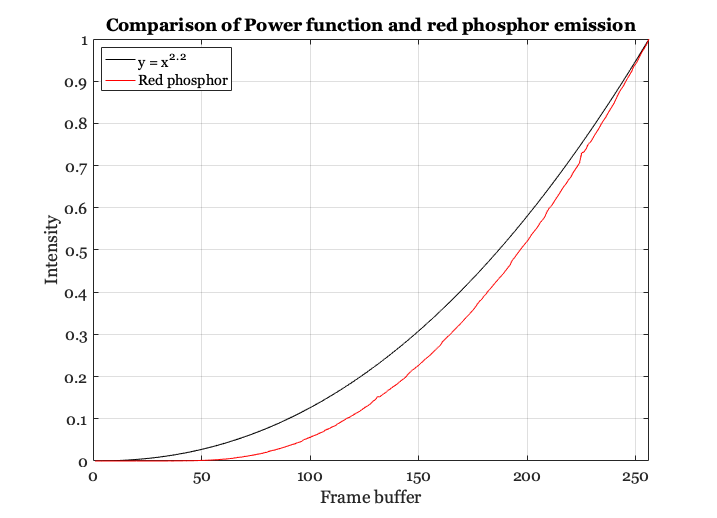

frameBuffer = 1:256;
pred = ((frameBuffer)/256).^(2.2);
plot(frameBuffer,pred,'k-',frameBuffer,monitorGam(:,1),'r-')
xlim([0 256]); xlabel('Frame buffer'); ylabel('Intensity');
title('Comparison of Power function and red phosphor emission')
legend('y = x^2^.^2', 'Red phosphor','Location', 'NorthWest');
grid on

### Displays differ

For this display, you can see that the fit is much better using a larger exponent, namely

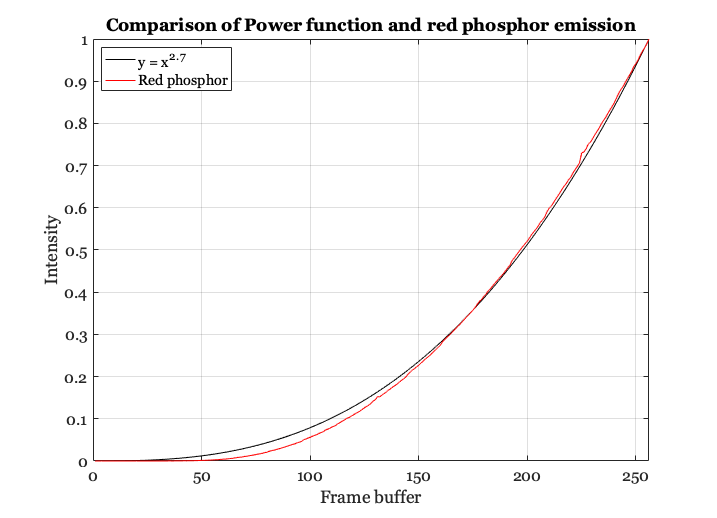

frameBuffer = 1:256;
pred = ((frameBuffer)/256).^(2.7);
plot(frameBuffer,pred,'k-',frameBuffer,monitorGam(:,1),'r-')
xlim([0 256]); xlabel('Frame buffer'); ylabel('Intensity');
title('Comparison of Power function and red phosphor emission')
legend('y = x^2^.^7', 'Red phosphor','Location', 'NorthWest');
grid on

Recall that we measured the emitted intensity using the maximum framebuffer value.  This corresponds to the column entries in phosphor, and these are the signals emitted when the relative framebuffer value is one. 

To specify the intensity of the emitted light for some other digital value, we can create a lookup table that represents the gamma function.  For example, the spectral power distribution of the light emitted by the green phosphor at a frame buffer level of 130 is

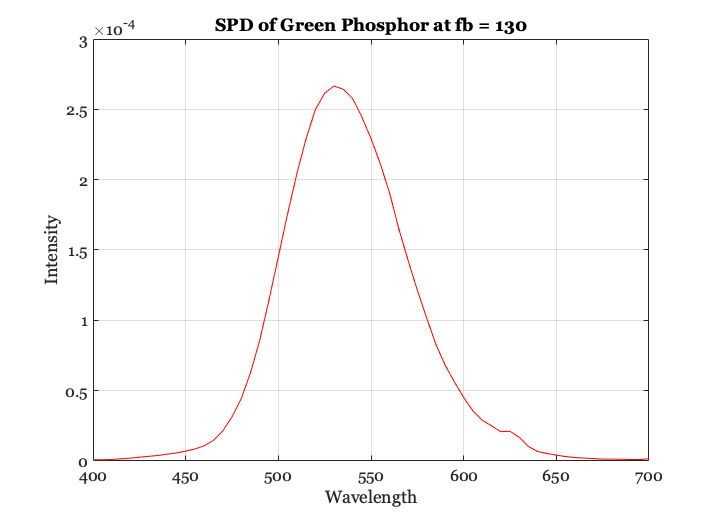

emitted = phosphors(:,2)*monitorGam(130,2);
plot(wavelength,emitted), grid on
xlabel('Wavelength')
ylabel('Intensity')
title('SPD of Green Phosphor at fb = 130');

### The inverse gamma

Frequently, we are interested in how to set the frame-buffer level in order to obtain a given linear output intensity.  To determine this, we must calculate the inverse of the "gamma" function.  If we have fit a simple polynomial to the gamma function, then we can calculate the frame-buffer setting by inverting the function.  So that given a linear intensity, we can calculate the digital value as 


$$dv = I ^ \frac{1/\gamma}$$


(ignoring the constant)

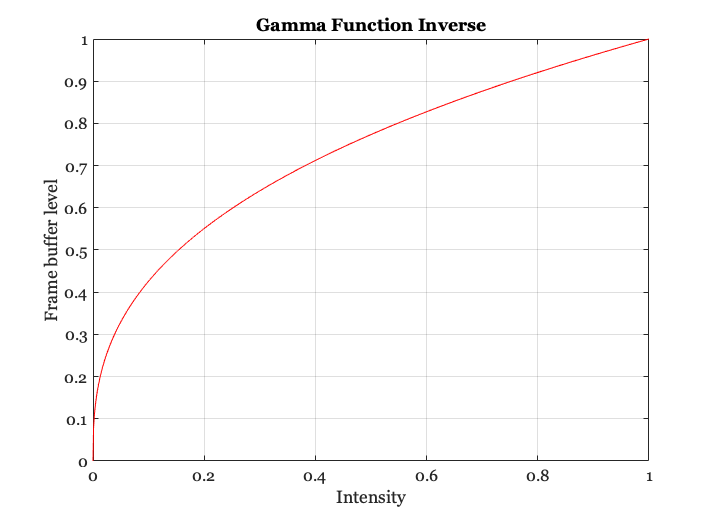

ieNewGraphWin;
intensity = 0:.001:1;
predFB = intensity.^(1/2.7);
plot(intensity,predFB)
xlabel('Intensity')
ylabel('Frame buffer level')
title('Gamma Function Inverse');
grid on

Another way to perform this calculation is by creating a look-up table that inverts the gamma function.  You might take a look at the code in the function "mkInvGammaTable" to see how Xuemei Zhang and I created inverse gamma look-up table functions.  To see the code enter "type mkInvGammaTable"

invGamTable = mkInvGammaTable(monitorGam,1000);

Gamma table 1 NOT MONOTONIC.  We are adjusting.
Gamma table 2 NOT MONOTONIC.  We are adjusting.
Gamma table 3 NOT MONOTONIC.  We are adjusting.


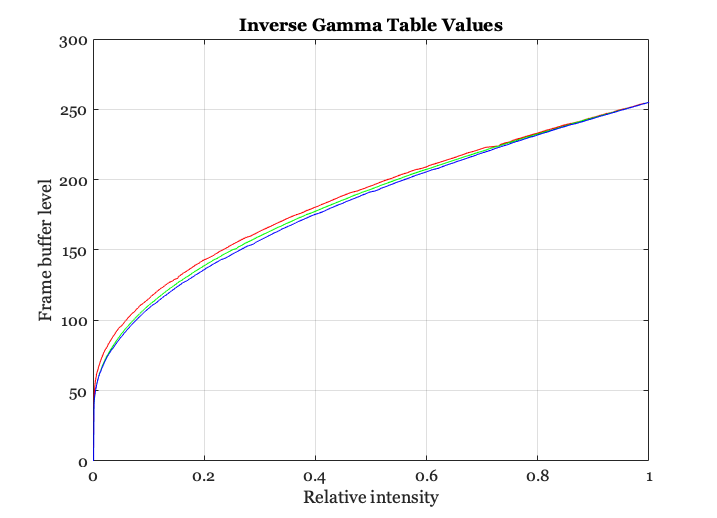

plot((1:1000)/1000,invGamTable), grid on
xlabel('Relative intensity')
ylabel('Frame buffer level')
title('Inverse Gamma Table Values');

(We make invGamTables with more than 8 bits of resolution because most of the frame buffers we have in the lab are 10 bits.)

To look up the frame buffer value that will produce a  particular linear intensity, then, we round the intensity to 1 part in a thousand (because there are a 1000 levels in the inverse table) and then use that as an index.  For example, to calculate the frame buffer values that generate linear  intensities of [.1 .3 .5 .7 .9] we calculate as

intensity = (.1:.2:.9);
intensityX = round(intensity*1000)

intensityX =    100   300   500   700   900


fb = round(invGamTable(intensityX,1))

fb =    115
   163
   196
   222
   244


Now, let's see how well we did.  Here are the intensities we will obtain with these digital values.

obtainedIntensity = monitorGam(fb,1)

obtainedIntensity =     0.0950
    0.2935
    0.4952
    0.6907
    0.8870


We can plot the obtained and desired intensities in a graph We are close, but because of the quantization of the device we do not obtain the exact linear intensities.

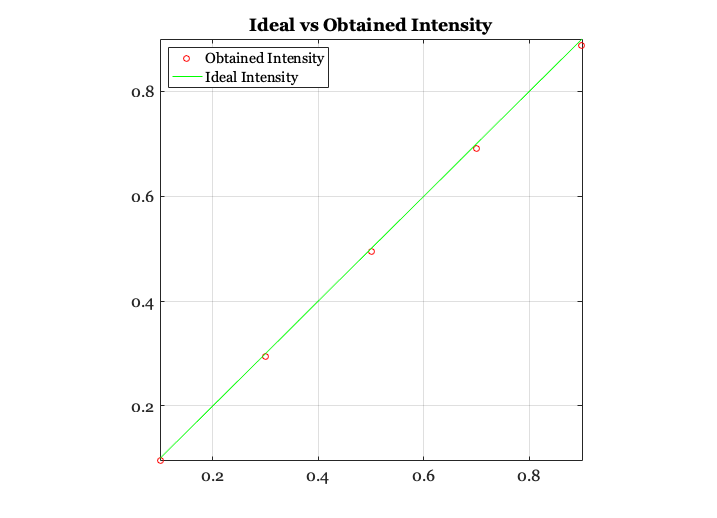


plot(intensity, obtainedIntensity, 'o', intensity, intensity,'-'), grid on
axis equal, axis square, axis tight
set(gca,'xtick',(0:.2:1),'ytick',(0:.2:1))
%identityLine = line([0 1],[0 1]);
legend('Obtained Intensity', 'Ideal Intensity', 'Location', 'NorthWest');
title('Ideal vs Obtained Intensity');

## Computing xy-chromaticity coordinates

The monitor is also described in terms of several different chromaticity coordinate measurements, namely its "white point" and the gamut of colors that it can reach. The white point is the chromaticity coordinates of the display when all three phosphors are set to maximum intensity. These can be computed as

% We put the XYZ values into the columns (note the transpose)
maxXYZ = ieXYZFromEnergy(phosphors',wavelength(:))';

whitePoint = chromaticity(sum(maxXYZ,2)')'

whitePoint =     0.2849
    0.3037



% The (x,y) chromaticity coordinates of the phosphors can be
% computed individually as

xyMonitor = chromaticity(maxXYZ')'

xyMonitor =     0.6237    0.2902    0.1490
    0.3430    0.6095    0.0757


### Graphing the xy coordinates

We can build a graph describing the chromaticity coordinates of the phosphors and the white point by first computing the xy coordinates of the spectrum.  Remember that the rows of xyz contain the XYZ values of each spectral light.  So, we can compute the chromaticity of the spectral lights as

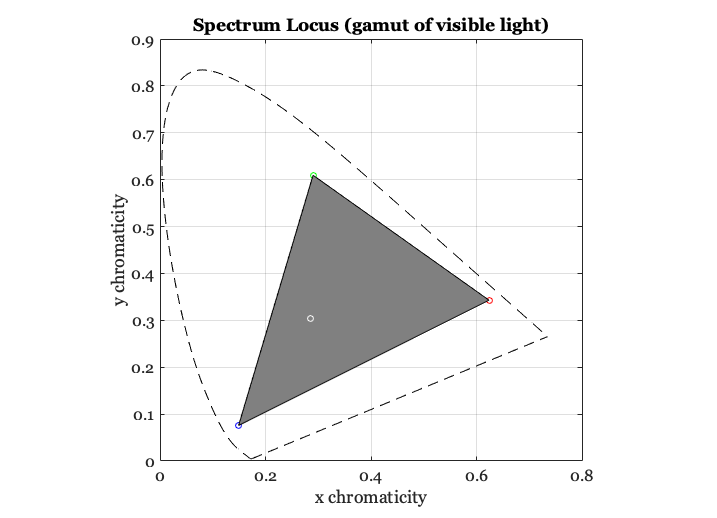

xySpectrum = chromaticity(XYZ)';
% Modified 01-06-2005 PC xySpectrum = chromaticity(XYZ');

% Now, we plot these values and turn on hold.  Any light is a
% mixture of spectral lights, so these values define an outer
% boundary for where any physical light can fall.

plotSpectrumLocus;  % Read this routine
axis equal, axis square
grid on, xlabel('x-chromaticity'), ylabel('y-chromaticity')
title('Spectrum Locus (gamut of visible light)');
hold on

% Overlay the xy coordinates of the three monitor phosphors on
% top of the graph

plot(xyMonitor(1,1),xyMonitor(2,1),'ro');
plot(xyMonitor(1,2),xyMonitor(2,2),'go');
plot(xyMonitor(1,3),xyMonitor(2,3),'bo');

% and place a patch over the region where sums of the phosphors
% can fall.  This is called the "gamut" of the display

p = patch(xyMonitor(1,:), xyMonitor(2,:), [.5 .5 .5]);

% Finally, add in the chromaticity coordinate of the white point
% and label the axes.

plot(whitePoint(1),whitePoint(2),'wo');
xlabel('x chromaticity'), ylabel('y chromaticity')
hold off


% Notice that the white point coordinates are not at the middle
% of the gamut.  The position of the white point depends on the
% sum of the (X,Y,Z) values from each of the phosphors.  These
% are unequal, with the green and blue being the largest.  Hence,
% the white point is closer to these two corners of the gamut 

sum(maxXYZ)

ans =    61.7836  110.1562  158.3428


## ISET makes it easy to plot the gamut

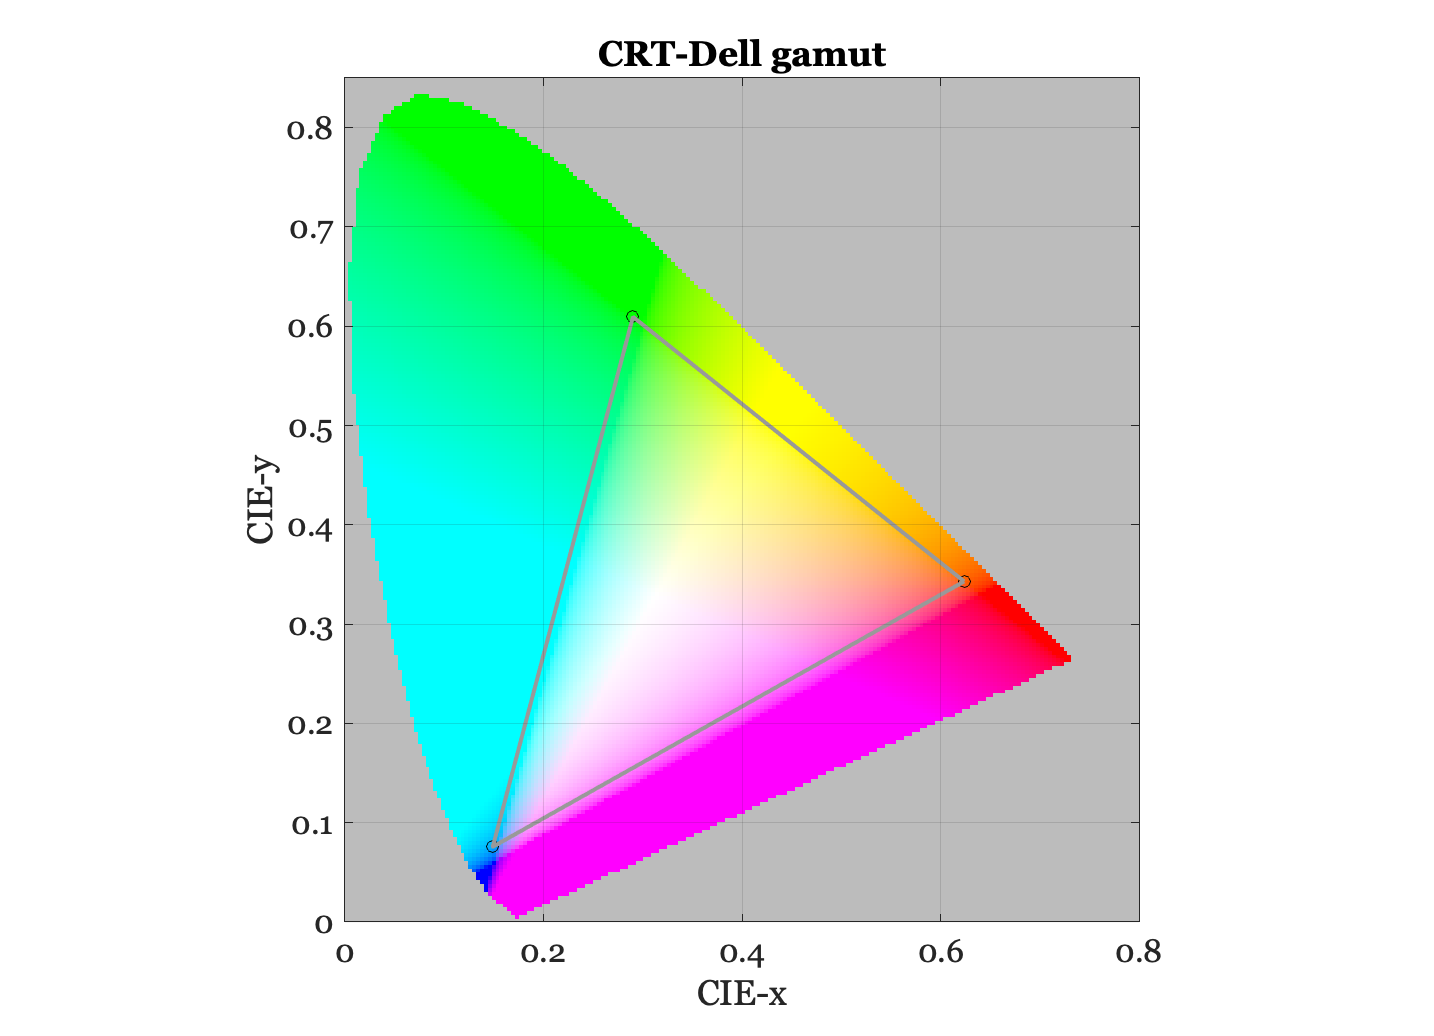

% These ideas are all embedded in the existing plotting routines. But the
% point of this script is to show you the ideas, not to plot the gamut.
displayPlot(d,'gamut');
title(sprintf('%s gamut',displayGet(d,'name')));

## TUTORIAL QUESTIONS

USING THE COLOR MATCHING FUNCTIONS

Consider a color matching experiment using a CRT monitor with phosphor spectral power distributions (SPD) given by 'phosphors' in cMatch/monitor.mat

a) Using the CIE-XYZ method, calculate what phosphor intensities you will need to match a monochrome light at 550nm. What phosphor intensities are needed to match a monochrome light at 430nm?

b) Plot the SPD of the phosphors that would make this match. Why are these intensities not physically realizable?

c) If you wanted to perform an experiment to test the predicted match, what could you do to arrange the viewing conditions?

COLOR MONITOR CALIBRATION AND CHROMATICITY

a) Let the SPDs of the three phosphors of a color monitor be R, G, and B. Let the value of a pixel be written as a vector x = [r,g,b], where r, g, and b are between 0 and 1. 

Write the matrix equation that expresses the SPD of a monitor pixel displaying the pixel x. (Ignore gamma correction)

b) How do the set of spectral power distributions emitted from a pixel compare with the spectral power distributions that are possible in the environment?

c) Typical monitors can modulate the linear phosphor intensity at 256 levels (8-bits). Suppose that you could modulate the phosphor intensities at 16-bit accuracy. Would this monitor produce better images? If you are not sure, then state what you need to know about the human visual system to decide whether the improvement is worthwhile.

d) Suppose that you are able to build a monitor with a fourth phosphor, not just the three that are usually built. In what sense would this monitor be better than a three-primary monitor? If you could set the x-y chromaticity of the phosphor, how would you design it to achieve the best monitor performance? You may want to sketch or plot a chromaticity diagram to show what you mean.

## Optional questions

Suppose you are an LCD manufacturer, and you know that if you had an ideal LCD, each of the R,G,B color channels would emit light according to the SPD given in monitors.mat. We have already plotted the color gamut of such a monitor.

In a real LCD display, the LC gates are not able to block 100% of the light from the backlight. Suppose that due to such leakage, the contrast ratio between a fully black and fully white display is 100:1. Plot the gamut of colors for this display and explain what happens.